# Factorización *PCA y NMF*

## Importación y limpiado de la imagen + detección de *blobs*

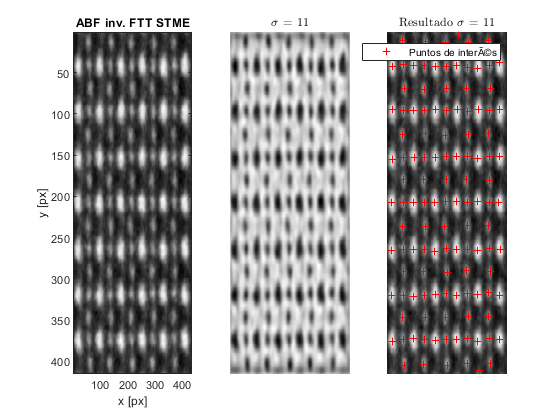

clc, clear, close all

% Leemos el mapa de bits que sale del microscopio
Ir = imread('../data/LSMO.png');
Ir = double(rgb2gray(Ir));

% Invertimos ABF
I = 255 - Ir;

% Normalizamos
Ir = Ir/max(max(Ir));
I = I/max(max(I));

% Limpiamos el ruido de la imagen con FFT
thresh = 0.001;
Yt = fft2(I);
Max = max(max(abs(Yt)));
ind = abs(Yt) > thresh*Max;
Atlow = single(Yt .* ind);
Ilow = double(ifft2(Atlow));

% Detección de blobs por NLoG (pesado de compilar)
sgm_list = 11;
[x,y] = blobDetector(Ilow,sgm_list,0.030,1);

## Extracción de los parches de información

Generamos la Figura 8 para visualizar cómo se va a construir la matriz $X$:

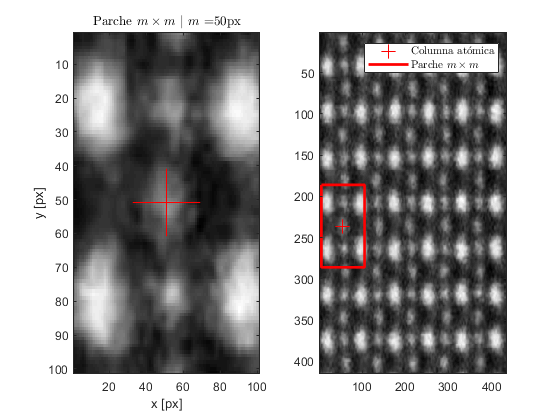

m = 50; % Distacia respecto al blob a cada lado
c = 9; % Elegimos una columna que cumpla las condiciones

figure(1), clf;

% Extraemos el parche seleccionado
I_patch = I(y(c)-m : y(c)+m ,x(c)-m : x(c)+m);
                                               
subplot(1,2,1)
imagesc(I_patch), colormap gray, hold on;
plot(m+1,m+1,'r+', 'MarkerSize', 50, 'LineWidth', 0.7)
title("Parche $m\times m$ $|$ $m = $" + num2str(m) + "px",'interpreter','latex')
xlabel("x [px]"), ylabel("y [px]")

% Dibujamos localización del parche en la imagen
x1 = x(c)-m; y1 = y(c)-m;
x2 = x(c)-m; y2 = y(c)+m;
x3 = x(c)+m; y3 = y(c)+m;
x4 = x(c)+m; y4 = y(c)-m;

subplot(1,2,2)
imagesc(I), colormap gray, hold on;
plot(x(c),y(c),'r+', 'MarkerSize', 10, 'LineWidth', 0.7)
plot([x1 x2 x3 x4 x1],[y1 y2 y3 y4 y1], "-r", "LineWidth",2)
legend("Columna at\'omica", "Parche $m\times m$",'interpreter', 'latex')

Una vez mostrado el proceso, generamos el tensor de información $T$ para posteriormente aplanarlo y transformarlo en la matriz $X$ que procesaremos por los distintos métodos de factorización matricial:

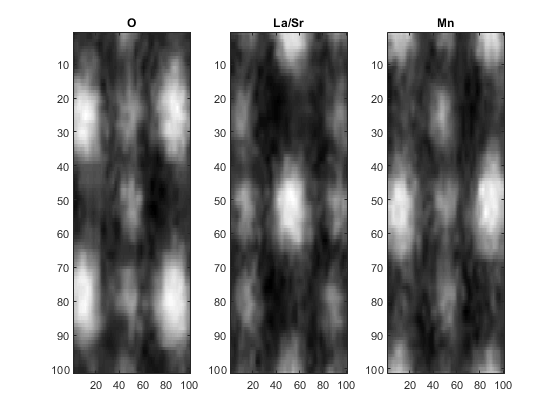

m = 50; % Distacia respecto al blob a cada lado

% Contabilizamos cuántos parches vamos a generar para inicializar T y X
patchs = 0;
for i = 1:length(x)
    if (x(i) > m && y(i) > m) && (x(i) < (size(I,2) - m) && y(i) < (size(I,1) - m))
        patchs = patchs + 1;
    end
end
T = zeros(2*m+1 ,2*m+1, patchs);
X = zeros(patchs, (2*m+1)^2);

% Extraemos todos los parches
patch = 1;
for i = 1:length(x)
    if (x(i) > m && y(i) > m) && (x(i) < size(I,2) - m && y(i) < size(I,1) - m)
        I_patch = I(y(i)-m : y(i)+m ,x(i)-m : x(i)+m);
        T(:,:,patch) = I_patch;
        patch = patch + 1;
    end
end

% Depuración para comprobar que T es correcto
%figure(), clf;
%imagesc(T(:,:,c)), colormap gray, hold on;

% Aplanamos el tensor
X = reshape(T, (2*m+1)^2, patchs)';

% Depuración para comprobar que X es correcto (igual a figure(2)?)
%figure(), clf;
%imagesc(reshape(X(c,:),2*m+1,2*m+1)), colormap gray, hold on;

% Separamos los datos entre train_data y test_data
n1 = 9;
n2 = 60;
n3 = 23;

X_train = X;
X_train(n1,:) = [];
X_train(n2,:) = [];
X_train(n3,:) = [];

X_test = [X(n1,:); X(n2,:); X(n3,:)];

% Mostramos un parche de cada tipo
figure(), clf;
colormap gray, hold on;
subplot(1,3,1)
imagesc(reshape(X_test(1,:),2*m+1,2*m+1))
title("O")
subplot(1,3,2)
imagesc(reshape(X_test(2,:),2*m+1,2*m+1))
title("La/Sr")
subplot(1,3,3)
imagesc(reshape(X_test(3,:),2*m+1,2*m+1))
title("Mn")

## Descomposición PCA $(X = UV')$

% Hacemos uso del algoritmo implementado en MATLAB
% (requiere "Statistics and Machine Learning Toolbox")
[V,U,s2] = pca(X_train);

% Nos quedamos con los dos primeros coeficientes porque son los que tienen
% una mayor varianza (s2)
disp("Varianza de 4 primeras PC")

Varianza de 4 primeras PC


disp(s2(1:4))

  151.7274
   37.8291
   11.5723
    2.9650




% Visualizamos las dos componentes principales escogidas
U = U/max(max(abs(U)));

figure(4), clf;
colormap gray; colorbar

subplot(4,4,[1 5 9]);
plot(U(:,1),U(:,2),".b"), grid on, hold on;
xlim([-1.2 1.2]), ylim([-1.2 1.2])
xlabel("Primera componente principal")
ylabel("Segunda componente principal")
title("PCA: Primeras dos componentes")

%biplot(V(:,1:2),'scores',score(:,1:2)), hold on;

% Mostramos la imagen reconstruida a partir de las
% primeras componentes principales
X_ = U(:,1:3)*V(:,1:3)';
X_ = X_/max(max(abs(X_)));
I_ = reshape(X_(c,:),2*m+1,2*m+1);
subplot(4,4,2);
imagesc(I_)
title("\textbf{PCA }$| \; X = U \times V$","Interpreter","latex")

% Mostramos las componentes por separado
I_1 = reshape(V(:,1),2*m+1,2*m+1);
subplot(4,4,6);
imagesc(I_1), colorbar, axis off
title("$V_p$ $|$ p = 1","Interpreter","latex")

I_2 = reshape(V(:,2),2*m+1,2*m+1);
subplot(4,4,10);
imagesc(I_2), colorbar, axis off
title("p = 2","Interpreter","latex")

I_3 = reshape(V(:,3),2*m+1,2*m+1);
subplot(4,4,14);
imagesc(I_3), colorbar
title("p = 3","Interpreter","latex")
xlabel("x [px]"), ylabel("y [px]")


## Descomposición NMF

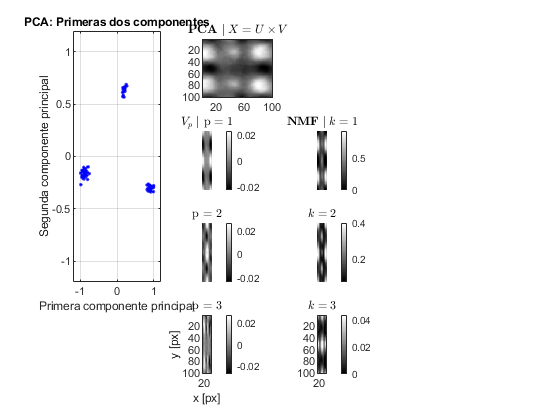

% Realizamos la factorización NMF
[Un,Vn] = nnmf(X,3);

% Mostramos las dos componentes
X_1 = Un(:,1)*Vn(1,:);
X_1 = X_1/max(max(abs(X_1)));
I_1 = reshape(X_1(c,:),2*m+1,2*m+1);
subplot(4,4,7);
imagesc(I_1), colorbar, axis off
title("\textbf{NMF }$| \; k = 1$","Interpreter","latex")

X_2 = Un(:,2)*Vn(2,:);
X_2 = X_2/max(max(abs(X_2)));
I_2 = reshape(X_2(c,:),2*m+1,2*m+1);
subplot(4,4,11);
imagesc(I_2), colorbar, axis off
title("$k = 2$","Interpreter","latex")

X_3 = Un(:,3)*Vn(3,:);
X_3 = X_3/max(max(abs(X_3)));
I_3 = reshape(X_3(c,:),2*m+1,2*m+1);
subplot(4,4,15);
imagesc(I_3), colorbar
title("$k = 3$","Interpreter","latex")

## Generación de vectores descriptores PCA

Teniendo en cuenta que en la descomposición PCA $X = UV'$, podremos generar los vectores descriptores para cada observación tomando $XV = U$. Cada  fila de la matriz resultante corresponderá al descriptor de la columna atómica en cuestión.

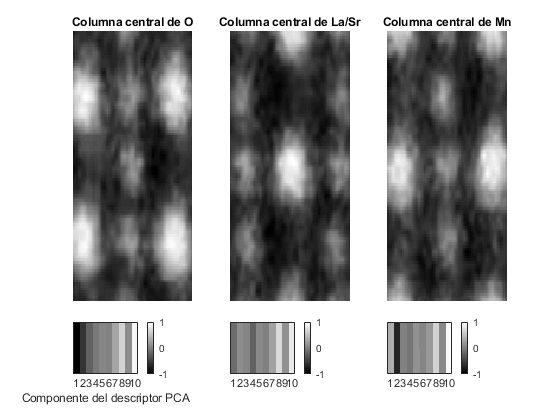

% Tomamos 2 columnas atómicas como ejemplo
% (corresponderan con los dos casos posibles)

% Representamos sus correspondientes parches
figure(2), clf;
colormap gray

n1 = 9;
subplot(5,3,[1 4 7 10])
imagesc(reshape(X(n1,:),2*m+1,2*m+1)), axis off
title("Columna central de O")

n2 = 60;
subplot(5,3,[2 5 8 11])
imagesc(reshape(X(n2,:),2*m+1,2*m+1)), axis off
title("Columna central de La/Sr")

n3 = 23;
subplot(5,3,[3 6 9 12])
imagesc(reshape(X(n3,:),2*m+1,2*m+1)), axis off
title("Columna central de Mn")

% Generamos los vectores descriptores
k = 10;

desc = [X(n1,:); X(n2,:); X(n3,:)] * V(:,1:k);
desc = desc./max(max(abs(desc)));

subplot(5,3,13)
imagesc(desc(1,:)), colorbar
caxis([-1 1])
set(gca,'xtick',1:k)
set(gca,'ytick',[])
xlabel("Componente del descriptor PCA")

subplot(5,3,14)
imagesc(desc(2,:)), colorbar
caxis([-1 1])
set(gca,'xtick',1:k)
set(gca,'ytick',[])

subplot(5,3,15)
imagesc(desc(3,:)), colorbar
caxis([-1 1])
set(gca,'xtick',1:k)
set(gca,'ytick',[])

## Seleccionamos los parches centrados en columnas de oxígeno 

% Buscamos todos los máximos locales y los marcamos
ids = [find(U(:,1) < 0)];

% Los guardamos limpios y con ruido
X_clean = zeros(length(ids),(2*m+1)^2);
X_noisy = X_clean;

for i = 1:length(ids)
    X_clean(i,:) = X_train(ids(i),:);
    X_noisy(i,:) = X_clean(i,:) + 0.25*randn(size(X_clean(i,:)));
    imwrite(uint8(reshape(X_clean(i,:),2*m+1,2*m+1)*255), "clean_patches/"+ num2str(i) +".png")
    imwrite(uint8(reshape(X_noisy(i,:),2*m+1,2*m+1)*255), "noisy_patches/"+ num2str(i) +".png")
end

writematrix(X_clean,"clean_patches/clean_stack.csv")
writematrix(X_noisy,"noisy_patches/noisy_stack.csv")

% Guardamos un caso en el que no hay oxigeno en el centro
imwrite(uint8(reshape(X(n2,:),2*m+1,2*m+1)*255), "clean_patches/anomaly.png")